## Matlab Vocabulary

#### Falling object with no air resistance:   -mg = my''        -g = y''

`    syms g b c y(t)` command that defines the symbols used for the constants and functions

`    diff(y,t,n)` means take the nth derivative of y w.r.t. t

         You can define your own symbols:

   `     D2y = diff(y,t,2), Dy = diff(y,t), equ = D2y = = -g `gives the differential equation)

         Solve differentual equations using different methods, ODE 45 and dsolve are common

   `     dsolve(equ, cond)`

**Specify symbols**

syms g b c y(t); 

**Specify first and second derivatives**

D2y = diff(y,t,2); 
Dy = diff(y,t);

**Specify differential equations to be solved**

equ = D2y == -g; % no air resistance, down is negative
cond = [y(0)==0, Dy(0)==0]; % specify initial conditions
dsolve(equ, cond); % solve differential equation

**Plot position vs time**

set(groot, 'DefaultAxesFontSize', 18) %change font to 18 to see (groot is graphical root object)
y1 = subs(ans, g, 10); %g = 10 m/s^2 and substitutue it in the equation

**Make graph from 0 to 5 seconds**

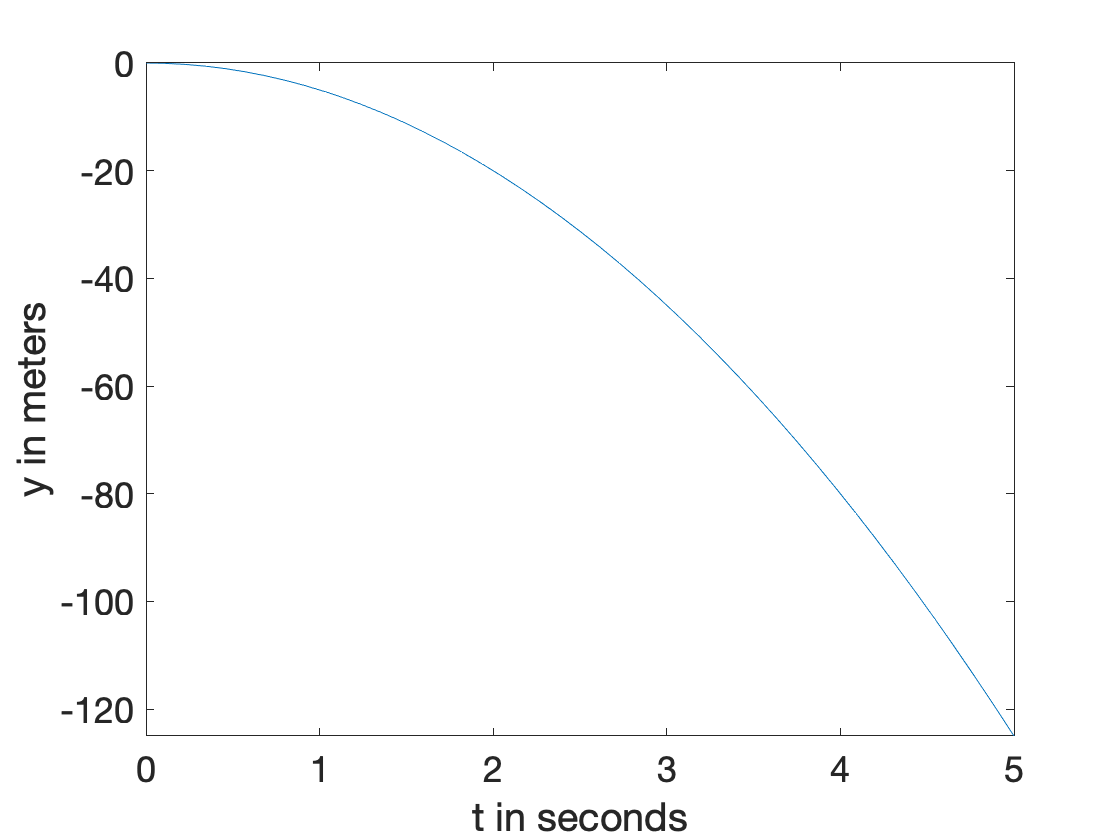

figure(1);
fplot(y1, [0,5])
xlabel('t in seconds')
ylabel('y in meters')

**Plot velocity versys time**

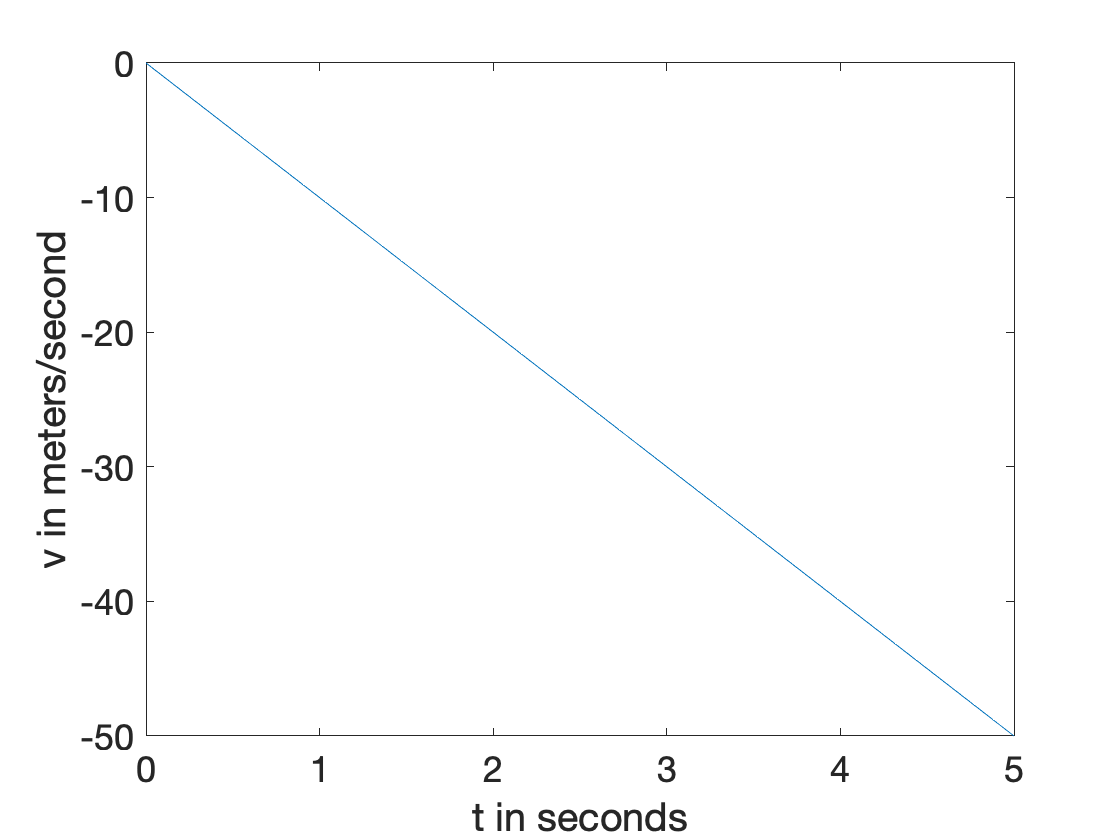

figure(2)
v = diff(y1, t);
fplot(v, [0,5])
xlabel('t in seconds')
ylabel('v in meters/second')

**Put both plots on the same graph**

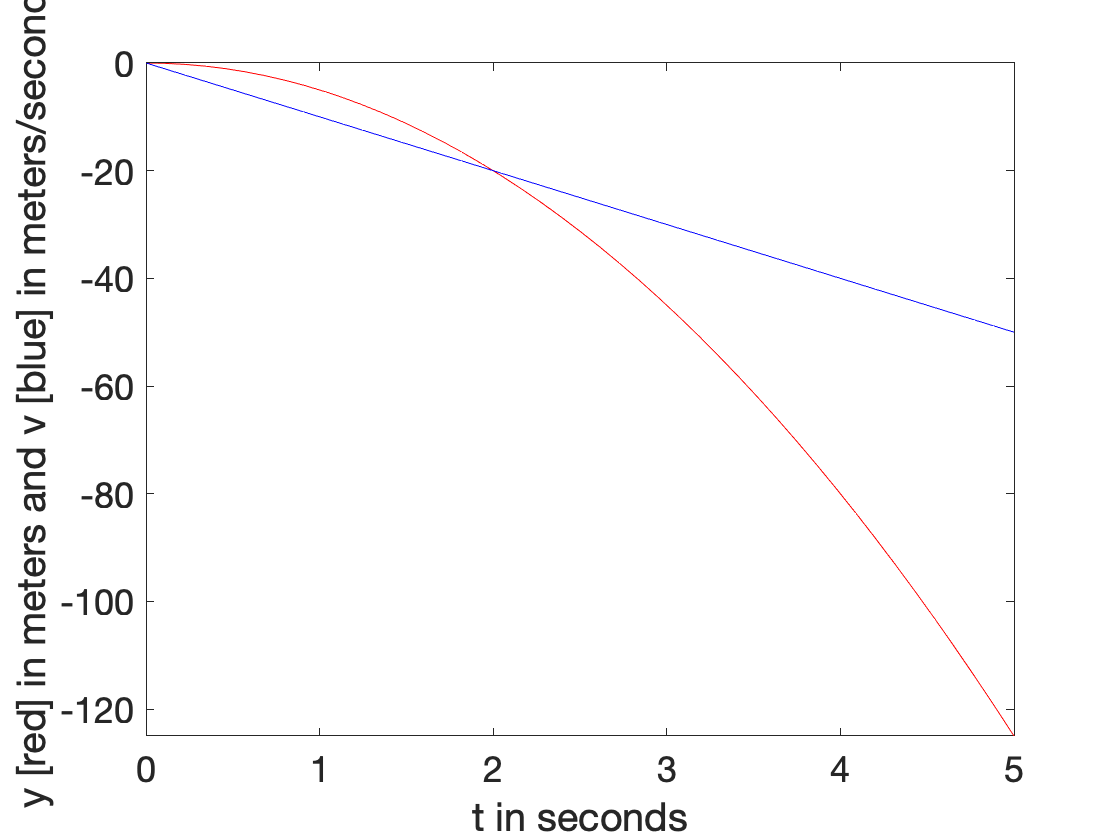

figure(3)
fplot(y1, [0,5], '-r')
xlabel('t in seconds')
ylabel('y in meters')
hold on
fplot(v, [0,5], '-b')
ylabel('y [red] in meters and v [blue] in meters/second')

**More Notes**

Using Matlab to solve dead fish equation...

put equation directly into dsolve 